# Allen Izuiqerdo HW6

## Problem #1

% Problems 1 and 2 uses figure 5.6 (textbook) to name identifiers, e.g. alpha is coupler displacment angle
clc;clf 
d2r = pi/180;
b2 = 20*d2r;    % beta
b3 = 50*d2r

b3 = 0.8727

a2 = -30*d2r;   % alpha
a3 = -50*d2r;
g2 = 60*d2r;    % gamma
g3 = 90*d2r;
P1 = [0,0];     % Precision Points
P2 = [2.4426,1.0108];
P3 = [2.4137,1.5017];

% Fundamental Dimensional Analysis Problem (DA), 3 Precision Points (3P), 3 Prescribed Angles (3A)
[W1, Z1, U1, S1] = fourBarSolveDA_3P_3A(P1,P2,P3,a2,a3,b2,b3,g2,g3)

W1 =     4.5246    0.9275


Z1 =    -0.6192    5.8995


U1 =     1.0220   -2.5253


S1 =     1.7383    1.9989



W = norm(W1); % linkage lengths
Z = norm(Z1);
U = norm(U1);
S = norm(S1);

theta = dir2D(W1); % linkage initial angles
sigma = dir2D(U1);
ZinitDir = dir2D(Z1);
SInitDir = dir2D(S1);

% Ground Links
a0 = P1 - Z1 - W1

a0 =    -3.9053   -6.8270


b0 = P1 - S1 - U1

b0 =    -2.7602    0.5264



% Constructing Kinematic Chains and Configurations
Chain1 = [W1;...
    Z1;
    -S1;
    -U1]

Chain1 =     4.5246    0.9275
   -0.6192    5.8995
   -1.7383   -1.9989
   -1.0220    2.5253


Chain2 = [Vec2D(W,theta + b2);...
    Vec2D(Z, ZinitDir + a2);...
    -Vec2D(S, SInitDir + a2);...
    -Vec2D(U, sigma + g2)]

Chain2 =     3.9345    2.4191
    2.4135    5.4187
   -2.5048   -0.8620
   -2.6980    0.3776


Chain3 = [Vec2D(W,theta + b3);...
    Vec2D(Z, ZinitDir + a3);...
    -Vec2D(S, SInitDir + a3);...
    -Vec2D(U, sigma + g3)]

Chain3 =     2.1978    4.0622
    4.1212    4.2665
   -2.6486    0.0467
   -2.5253   -1.0220


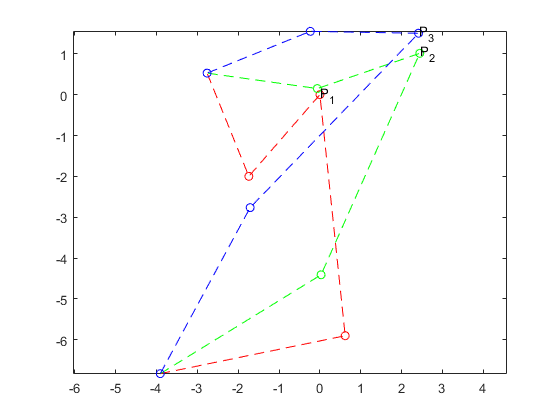


% Draw Chains in 2D Space
Offset = a0;
drawKinematicChain2D(Chain1, Offset, '--ro')
hold on;
drawKinematicChain2D(Chain2, Offset, '--go')
drawKinematicChain2D(Chain3, Offset, '--bo')
text(P1(1), P1(2),'P_1');
text(P2(1), P2(2),'P_2');
text(P3(1), P3(2),'P_3');

## Problem #2

clc,clf;
d2r = pi/180;   % See Previous Problem
b2 = -10*d2r;
b3 = -30*d2r

b3 = -0.5236

a2 = -70*d2r;
a3 = -107*d2r;
g2 = 15*d2r;
g3 = 35*d2r;
P1 = [0,0];
P2 = [2.4696,3.1993];
P3 = [5.5634,3.8500];

% Fundamental Dimensional Analysis Problem (DA), 3 Precision Points (3P), 3 Prescribed Angles (3A)
[W1, Z1, U1, S1] = fourBarSolveDA_3P_3A(P1,P2,P3,a2,a3,b2,b3,g2,g3)

W1 =    -2.8841    2.7285


Z1 =    -2.9325    0.0239


U1 =    -0.6055   -3.2954


S1 =    -3.1143   -0.4822



W = norm(W1); % links lengths
Z = norm(Z1);
U = norm(U1);
S = norm(S1);

theta = dir2D(W1); % links initial angles
sigma = dir2D(U1);
ZinitDir = dir2D(Z1);
SInitDir = dir2D(S1);

% Ground Links
a0 = P1 - Z1 - W1

a0 =     5.8166   -2.7524


b0 = P1 - S1 - U1

b0 =     3.7198    3.7776



% Constructing Kinematic Chains and Configurations
Chain1 = [W1;...
    Z1;
    -S1;
    -U1]

Chain1 =    -2.8841    2.7285
   -2.9325    0.0239
    3.1143    0.4822
    0.6055    3.2954


Chain2 = [Vec2D(W,theta + b2);...
    Vec2D(Z, ZinitDir + a2);...
    -Vec2D(S, SInitDir + a2);...
    -Vec2D(U, sigma + g2)]

Chain2 =    -2.3665    3.1879
   -0.9805    2.7638
    1.5182   -2.7616
   -0.2680    3.3398


Chain3 = [Vec2D(W,theta + b3);...
    Vec2D(Z, ZinitDir + a3);...
    -Vec2D(S, SInitDir + a3);...
    -Vec2D(U, sigma + g3)]

Chain3 =    -1.1335    3.8051
    0.8802    2.7974
   -0.4494   -3.1192
   -1.3941    3.0467


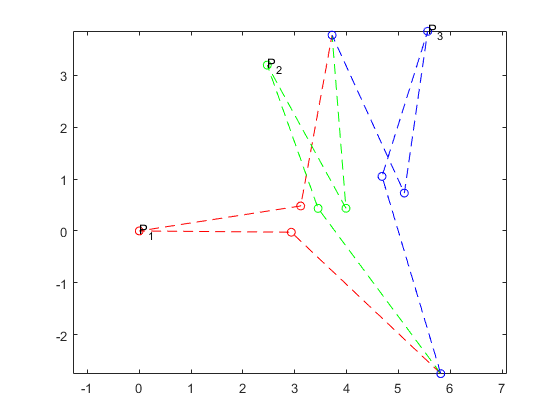


% Draw Chains in 2D Space, offset vector loop by ground link position 
Offset = a0;
drawKinematicChain2D(Chain1, Offset, '--ro')
hold on;
drawKinematicChain2D(Chain2, Offset, '--go')
drawKinematicChain2D(Chain3, Offset, '--bo')
text(P1(1), P1(2),'P_1');
text(P2(1), P2(2),'P_2');
text(P3(1), P3(2),'P_3');

## Problem #4

clc,clf
d2r = pi/180;
a2  = 5*d2r; % Alpha
a3 = -5*d2r;
b2 = 30*d2r; % Beta
b3 = 60*d2r;
g2 = 65*d2r; % Gama
g3 = 130*d2r;
G1 = Vec2D(1,0); % Constant Ground Link Vectorrr
G = norm(G1);
% Solve for Link Vectors (G = 1)
[W1, V1, U1] = fourBarSolveDA_3A_1G(G,a2,a3,b2,b3,g2,g3)

W1 =     0.5325    0.2935


V1 =     0.7991   -0.2885


U1 =     0.3316    0.0050



theta = dir2D(W1); % Crank Angle
rho = dir2D(V1); % Coupler
sigma = dir2D(U1); % Follower

W = norm(W1) % Crank Length

W = 0.6080

V = norm(V1) % Coupler

V = 0.8496

U = norm(U1) % Follower

U = 0.3316


% Link Configurations
W2 = Vec2D(W, theta + b2);
V2 = Vec2D(V, rho + a2);
U2 = Vec2D(U, sigma + g2);
W3 = Vec2D(W, theta + b3);
V3 = Vec2D(V, rho + a3);
U3 = Vec2D(U, sigma + g3);

% Precision Points
P1 = W1 + V1

P1 =     1.3316    0.0050


P2 = W2 + V2

P2 =     1.1356    0.3026


P3 = W3 + V3

P3 =     0.7830    0.2508


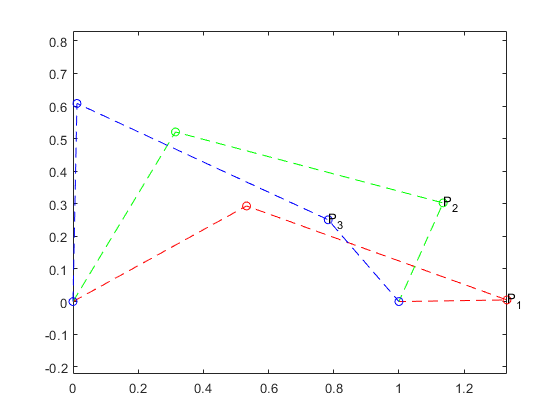


% Formulate Vector Chains for configurations and graphing
Chain1 = [W1;V1;-U1];
Chain2 = [W2;V2;-U2];
Chain3 = [W3;V3;-U3];

Offset = [0,0];
drawKinematicChain2D(Chain1, Offset, '--ro')
hold on;
drawKinematicChain2D(Chain2, Offset, '--go')
drawKinematicChain2D(Chain3, Offset, '--bo')
text(P1(1), P1(2),'P_1');
text(P2(1), P2(2),'P_2');
text(P3(1), P3(2),'P_3');